# Unit 3 / SDM / CE3.1: SDM with convex functions.

## Introduction

This exercise is to be carried out individually. 

In this exercise you will:

- Develop your own implementation of function `uosol``,``uosol_st.m` for the SDM.

- Use your implementation of the SDM to study the performance of SDM with convex functions, and how ill-conditioned hessians affects the convergence of the SDM.

In order to do this exercise you need:

- Library [`uolib`](https://www-eio.upc.edu/~fjheredia/files/uo/uolib.mlx), downloadable from the link to [`uolib.zip`](https://www-eio.upc.edu/~fjheredia/files/uo/uolib.zip).

- Function `upBLS_st.m`.

- The solution of [theoretical exercise TE3.3](https://www-eio.upc.edu/~fjheredia/files/uo/uo_SDM_TE.mlx).

The **deliverable** of this exercise is a `.zip` file `surname1-surname2.zip` that must be uploaded to Atenea before due date.

The contents of `.zip` file must be:

- This `.mlx` file with your answers to the all the questions.

- The codes `uoBLS_st.m` and `uosol_st.m` used in your answers.

This `.mlx` must be run in the same folder as the functions `uolib`, or you must include the `uolib` folder in the [Matlab's path](https://es.mathworks.com/help/releases/R2024b/matlab/ref/path.html?searchHighlight=path&s_tid=doc_srchtitle). 

Table of contents.

## Description.

As seen in exercise [TE3.3](https://www-eio.upc.edu/~fjharedia/files/uo/uo_SDM_TE.mlx) the convexity properties, minimizers of function $f\left(x\right)={x_1 }^2 +{x_2 }^4 +\frac{a\,{x_2 }^2 }{2}$, as well as the convergence of the SDM when applied to the problem $\min_{x\in \Re^2 } \;f\left(x\right)$ depends on the value of parameter $a$, being $f$convex whenever $a\ge 0$. In this computational exercise you are going to study the behaviour of SDM on to convex $f$ and how ill-conditioned hessians affects its convergence.

Table of contents.

## Questions

### **a) Computational convergence**

- For a=2 and a=0 , solve $\min_{x\in \Re^2 } \;f\left(x\right)={x_1 }^2 +{x_2 }^4 +a\frac{{x_2 }^2 }{2}\;$ with your own implementation of the SDM. Take $x^1 =\left\lbrack \begin{array}{c}
0\ldotp 5\\
1
\end{array}\right\rbrack$, $\epsilon_G ={10}^{-8}$ and $\delta =0\ldotp 001$. (solution)

- Analyse the observed computational global and local convergence. (solution)

### **b) Properties of the algorithms.**

- Discuss the observed computational convergence in terms of the theoretical properties of the SDM. (solution)

Table of contents.

## Solution

### **a) Computational convergence.**

#### Case a = 2

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^4+a*x(2)^2/2
   epsG = 1.0e-08, maxiter =  500
   iAC = 2 (SWC)
      almin = 1.0e-06, almax =  1.00, rho = 0.50, c1 = 0.01, c2 = 0.90
   isd = 1 (GM)
   ek = fk-f*
   x1 = [ +5.0e-01 , +1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC    ||g||        f         r        M
      1 -3.7e+01 +2.50e-01 SWC +6.1e+00 +2.2e+00 +1.67e-01 +7.4e-02
      2 -2.5e+00 +5.00e-01 SWC +1.6e+00 +3.8e-01 +1.77e-01 +4.7e-01
      3 -3.2e-01 +5.00e-01 SWC +5.6e-01 +6.6e-02 +1.47e-02 +2.2e-01
      4 -3.9e-03 +5.00e-01 SWC +6.3e-02 +9.8e-04 +3.81e-06 +3.9e-03
      5 -1.5e-08 +5.00e-01 SWC +1.2e-04 +3.7e-09 +3.81e-06 +3.9e-03
      6                        +9.1e-13 +2.1e-25
      k     g'*d        al  AC    ||g||        f         r        M
   la1 = +2.0e+00, lan = +2.0e+00, rUB = +0.00 
   x* = [ +0.0e+00 , -4.5e-13 ]
   [uosolLog]


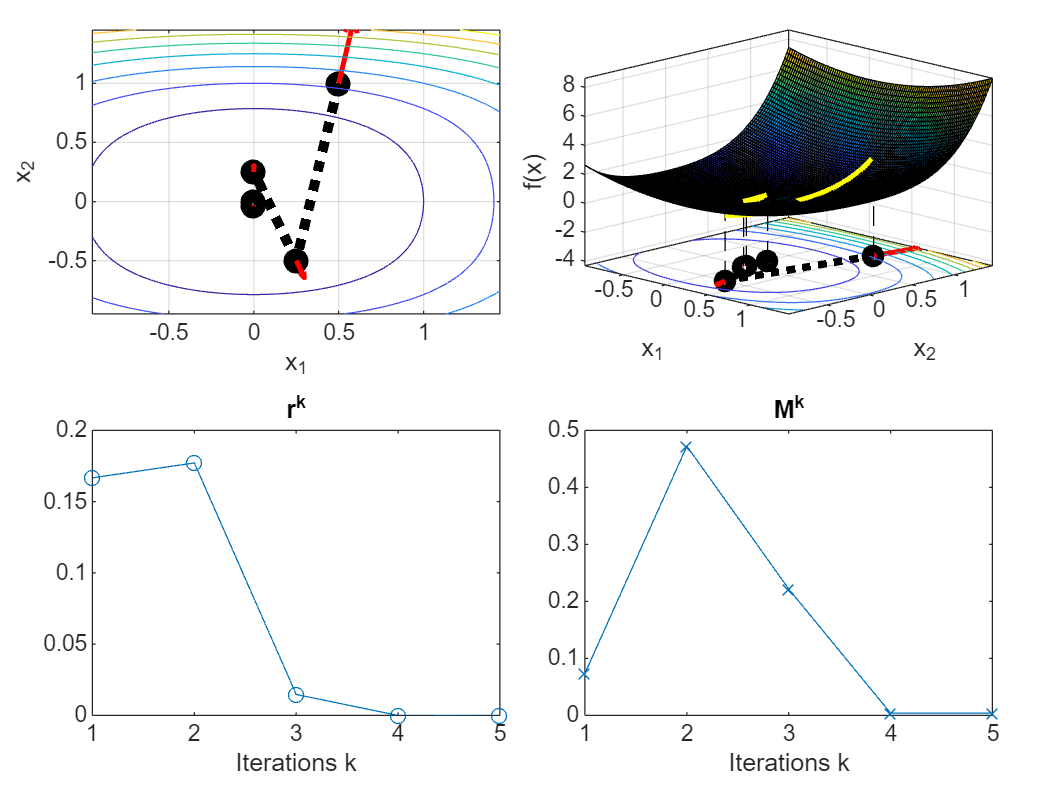

clear; syms x [2 1] real; 
a = 2;
P.f = @(x) x(1)^2+x(2)^4+a*x(2)^2/2;
P.g = @(x) [2*x(1); 4*x(2)^3+a*x(2)];
P.h = @(x) [2, 0; 0, 12*x(2)^2+a];

par.epsG = 10^-8;
par.maxiter = 500;        
par.iAC = 2;
par.almax = 1;       
par.almin = 10^-6;                
par.rho =0.5;
par.c1 = 0.01;
par.c2 = 0.9;
par.isd = 1;
par.delta = 0.001;

x1 = [0.5; 1];

[sol,par] = uosol_st(P,x1, par);

#### Case a = 0

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^4+a*x(2)^2/2
   epsG = 1.0e-08, maxiter =  500
   iAC = 2 (SWC)
      almin = 1.0e-06, almax =  1.00, rho = 0.50, c1 = 0.01, c2 = 0.90
   isd = 5 (MNM-SD)
      delta = 1.0e-03
   ek = ||gk||
   x1 = [ +5.0e-01 , +1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC   la1(h)      delta     k(B)    ||g||        f         r        M
      1 -1.8e+00 +1.00e+00 SWC +2.0e+00 >= 1.0e-03 +6.0e+00 +4.1e+00 +1.2e+00 +2.87e-01 +7.0e-02
      2 -2.6e-01 +1.00e+00 SWC +2.0e+00 >= 1.0e-03 +2.7e+00 +1.2e+00 +2.0e-01 +2.96e-01 +2.5e-01
      3 -5.2e-02 +1.00e+00 SWC +2.0e+00 >= 1.0e-03 +1.2e+00 +3.5e-01 +3.9e-02 +2.96e-01 +8.4e-01
      4 -1.0e-02 +1.00e+00 SWC +1.1e+00 >= 1.0e-03 +1.9e+00 +1.0e-01 +7.7e-03 +2.96e-01 +2.8e+00
      5 -2.0e-03 +1.00e+00 SWC +4.7e-01 >= 1.0e-03 +4.3e+00 +3.1e-02 +1.5e-03 +2.96e-01 +9.6e+00
    491 -9.7e-12 +9.54e-07 WC1 +1.0e-04 <  1.0e-03 +2.0e+03 +9.9e-08 +7.2e-11 +1.00e+00 +1.0e+07
    492 -9.7e-12 +9.54e-07 WC1

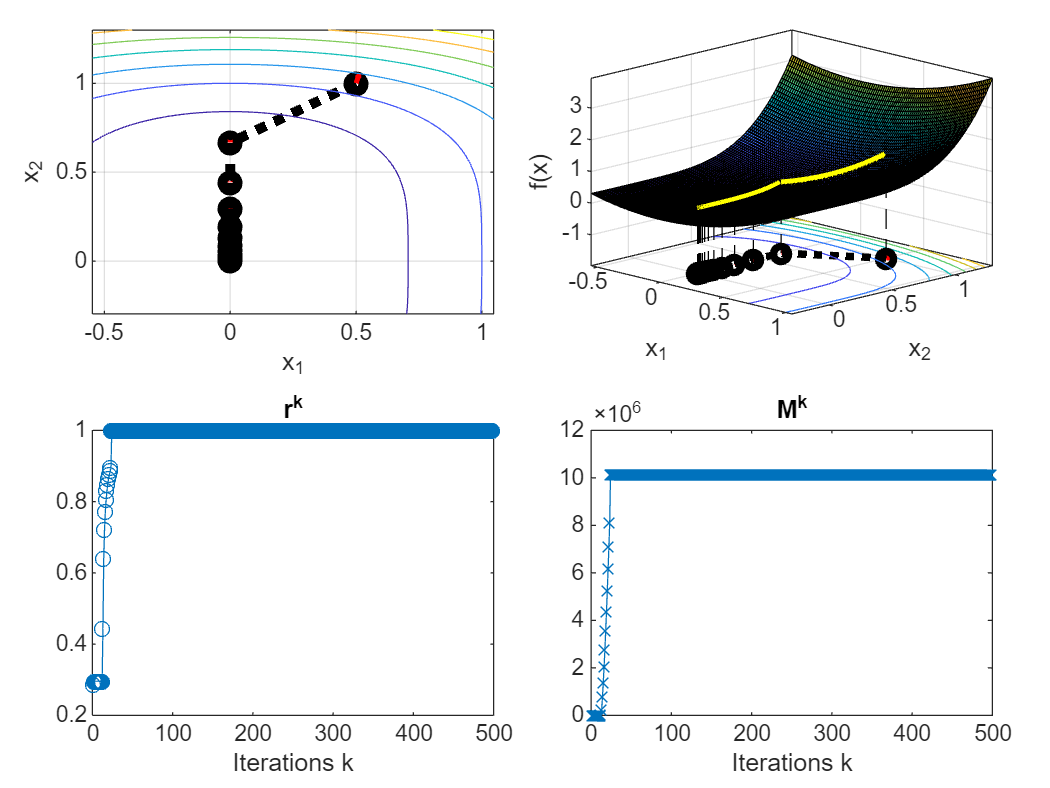

clear; syms x [2 1] real; 
a = 0;
P.f = @(x) x(1)^2+x(2)^4+a*x(2)^2/2;
P.g = @(x) [2*x(1); 4*x(2)^3+a*x(2)];
P.h = @(x) [2, 0; 0, 12*x(2)^2+a];

par.epsG = 10^-8;
par.maxiter = 500;        
par.iAC = 2;
par.almax = 1;       
par.almin = 10^-6;                
par.rho =0.5;
par.c1 = 0.01;
par.c2 = 0.9;
par.isd = 5;
par.delta = 0.001;

x1 = [0.5; 1];

[sol,par] = uosol_st(P,x1, par);

#### **Analysis.**

**Global convergence:**

Metode de Newton: convergencia global depen de que la Hessiana sigui definida positiva en els punts on itera.

- $a=2$ convergeix quadàticament, ja que $r\to 0,\quad M<C$ acotat.

Pel Newton modificat no hauria de canviar res, ja que la Hessiana ja és def pos.

For a = 2 it seems to converge perfectly, as the final iteration lands on the minimizer of the function. 

For a = 0 it seems like it gets closer to the minimizer, but it never reacher itto the minimizer.

**Local convergence:**

Metode de Newton: depen de si es compleix SOSC a $x^* $

For a = 2 $r\to 0,\quad M\to \infty$, with quadratic convergance.

For a = 0  $r$ doesn't converge to 0 and $M$ doesn't tend to infinite, so it doesn't have local convergence.

(Questions)